# **PageRank : Script e Test dell'Algoritmo**

Il seguente script mostra l'utilizzo dell'Algoritmo di PageRank implementato leggendo la matrice di Adiacenze G e un array U di URL da un file esterno o adoperando la funzione *"surfer".*

## Descrizione

Lo script calcola:

- Il PageRank della Matrice di Adiacenza G,

- Mostra la sparsità della stessa attraverso un grafico,

- Mostra i primi 15 risultati in ordine decrescente in termini di Outdegree e Indegree,

- Ricava un grafico a barre dei PageRank calcolati,

- Mostra un sottografo orientato dove i nodi rappresentano le pagine web con rank maggiore della media dei rank.

Inoltre vengono effettuati dei casi di test sulla correttezza dell'algoritmo implementato e sulla performance dello stesso prendendo come riferimento la funzione `centrality` del MATLAB. Infine vengono effettuati dei casi di test sulla robustezza dell'algoritmo.

# Utilizzo

Per prima cosa bisogna liberare il workspace, caricare la matrice G e l'array U attraverso lo script `surfer.`

clear
[U,G] = surfer('http://www.unina.it',100);
%load mathwork200.mat
%load repubblica.mat

*NB: In alternativa alla funzione *`surfer `*è possibile caricare uno tra i file *`"mathwork200.mat" `*e *`"repubblica.mat" `* che contengono già la matrice G e l'array U.*

## **Struttura della Matrice G**

Per visualizzare la struttura della matrice G viene utilizzato il comando `spy` che mostra un grafico della sparsità della matrice.

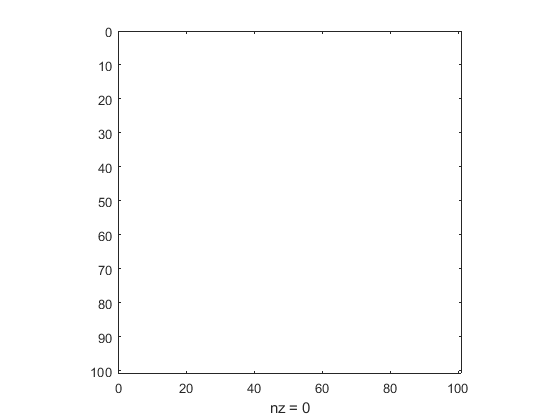

spy(G)

## Grafo Associato alla Matrice G

In allegato alla struttura della matrice G, viene ricavato il grafo associato ad essa. Ogni nodo del grafo rappresenta l'identificativo della pagina e ogni arco i collegamenti tra le pagine.

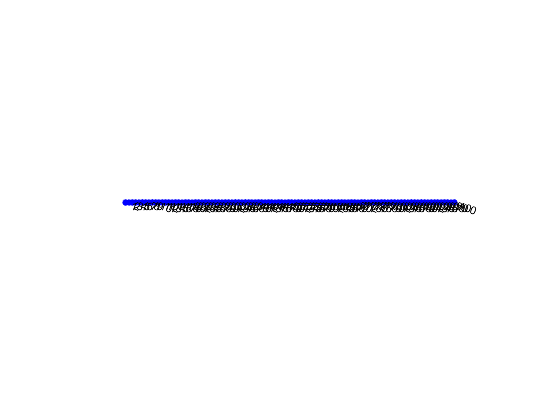

grafo = digraph(G');
plot(grafo,'NodeColor','b','EdgeColor',[.3 .3 .3]);
axis off

## Uso dell'Algoritmo di PageRank

Una volta ottenuta la matrice G e l'array U, è possibile ottenere dall'algoritmo di PageRank il vettore dei Rank delle pagine con i vettori  Outdegree ed Indegree associati a ciascuna pagina. Questi ultimi saranno poi rappresentati sul grafo associato alla matrice G.

*N.B : Per informazioni sull'Algoritmo di PageRank si faccia riferimento alla documentazione specificata nel file "Documentazione_PageRank.pdf".*

[R,Outdeg,Indeg] = PageRank(G);
grafo.Nodes.PageRank = R;
grafo.Nodes.InDegree = Indeg;
grafo.Nodes.OutDegree = Outdeg;

## Tabella degli Outdegree e Indegree

Mostriamo dunque di seguito i primi 15 Rank prodotti dall'algoritmo in ordine decrescente, con i rispettivi Identificativi, OutDegree, InDegree nel grafo.

[R,indice] = sort(R,'descend');
siti_web = U(indice(1:15));
id = indice(1:15);
ranks = R(1:15);
outdegrees = Outdeg(indice(1:15));
indegrees = Indeg(indice(1:15));
table(id,ranks,outdegrees,indegrees,'RowNames',siti_web)

Error using matlab.internal.tabular.private.rowNamesDim/validateAndAssignLabels (line 109)
The RowNames property must be a cell array, with each element containing one nonempty character vector.

Error in matlab.internal.tabular.private.tabularDimension/setLabels (

## Istogramma dei PageRank

Di seguito mostriamo un istogramma dei PageRank ottenuti dall'algoritmo.

bar(grafo.Nodes.PageRank)

## Sottografo dei PageRank

Associato all'istogramma, mostriamo il sottografo dei nodi con PageRank maggiore della media.

condition = find(grafo.Nodes.PageRank > mean(grafo.Nodes.PageRank));
sotto_grafo = subgraph(grafo,condition);
plot(sotto_grafo,'NodeLabel',condition,'NodeCData',sotto_grafo.Nodes.PageRank,'Layout','force');
colorbar;
axis off;

# Calcolo  Accuratezza

Viene valutata l'accuratezza dell'algoritmo trattato mediante un confronto con la funzione `centrality del MATLAB,i risultati sono mostrati nella tabella successiva.`

Calcolo_Accuratezza()

# Test di Robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 8 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Di seguito sono mostrati i casi di test più rilevanti che sono stati effettuati, rispettando la precedenza tra essi.

## Test case 3

Verifica l'errore nel caso in cui la matrice G è non sparsa.

**Input**


$$G=\mathrm{rand}\left(10\right)$$


## Test case 5

Verifica l'errore nel caso in cui la matrice G è sparsa ma non quadrata.

**Input**


$$G=\mathrm{rand}\left(10,15\right)$$


## Test case 6

Verifica l'errore nel caso in cui la matrice G non è logica.

**Input**


$$G=\mathrm{round}\left(\mathrm{sprand}\left(10,10,0\ldotp 2\right)*10\right)$$


## Test case 7

Verifica il warning nel caso in cui la matrice G contenga dei selfloops.

**Input**


$$G=\mathrm{logical}\left(G+\mathrm{speye}\left(\mathrm{size}\left(G\right)\right)\right)$$


## Esecuzione Test Suite

Vengono effettuati in modo automatizzato i casi di test sugli input definiti in precedenza.

results = runtests('CasiTest.m')

Riportiamo su una tabella i casi di test effettuati.

table(results)

In particolare l'ultimo caso di test effettuato verifica il funzionamento dell'algoritmo nel caso in cui sono presenti self loops (pagine che si autoreferenziano). Queste non devono essere considerate nel calcolo del rank, per tale motivo il caso di test genererà un warning. Riportiamo per completezza il comportamento di quest'ultimo caso di test.

results = runtests('CasiTest.m','ProcedureName','TestCase7')

## Riferimenti               

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

- Misura di Performance in Matlab [https://it.mathworks.com/help/matlab/performance-and-memory.html](https://it.mathworks.com/help/matlab/performance-and-memory.html)

- PageRank - Wikipedia [https://it.wikipedia.org/wiki/PageRank](https://it.wikipedia.org/wiki/PageRank)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**